# Week 1: Intro to Matlab and Simulink

*    Robert Garrone*

*    Worcester Polytechnic Institute, regarrone@wpi.edu*

## Introduction:

The problem statement is given as:

- Write down the function g(t) that has the shape of a sine wave that increases linearly in frequency from 0Hz at t = 0s to 5Hz at t = 10s.

- Plot the graph of this function using MATLAB's plot command.

- Add to the same figure in a different color a graph of the same function sampled continuously at 5Hz.

The approach taken is to first identify the type of signal that increases linearly over time and then generate that signal in MATLAB for the two cases given. Next, the linearly increasing signals are implemented using MATLAB. Finally, the signals are graphed onto one plot for comparison. 

## Materials and Methods

A chirp is a function whose frequency increases over time. The rate of change can be linear,logarithmic or at some other mathematically defined rate.  

To generate a chirp from 0 to 5 Hz, start and stop frequency variables `f_0` and `f_1` are initialized to the values 0 and 5 respectively:

f_0 = 0; %start freq
f_1 = 5; %end freq

Next, two different arrays of evenly spaced time values from 0 seconds ot 10 seconds are initialized using the `linspace` function. One array contains 1000 values or "points" from 0 to 10 seconds for an effective sampling rate of 100 samples/sec. The other contains 50 points between 0 and 10 seconds for an effective sampling rate of 5 samples/sec

t = linspace(0,10,1000); %1000 points for 10s (100Hz)
t_a = linspace(0,10,50); %50 points for 10s (5Hz) for aliased chirp

With start frequency, stop frequency, the 100 samples/sec array and the 5 samples/sec array defined, the chirp signals are now defined as:

g_t = chirp(t,f_0,10,f_1,'linear',-90); %100 sample/sec chirp
g_ta = chirp(t_a,f_0,10,f_1,'linear',-90); %5 sample/sec chirp

MATLAB provides a built-in chirp function `chirp` to aid in the generation of chirp waveforms. The last parameter passed to `chirp` in both function calls, -90, specifies the phase. -90 was chosen to make the signal appear as a swept sine wave as desired in the problem statement.

## Results

The function:

g_t = chirp(t,f_0,10,f_1,'linear',-90); %100 sample/sec chirp

is plotted using the plot function and associated `xlabel` and `ylabel` functions.

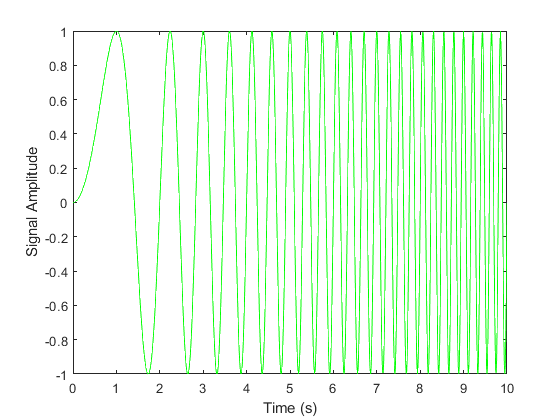

plot(t,g_t,'g');
xlabel('Time (s)')
ylabel('Signal Amplitude')

The figure shows a linearly increasing sine-wave shaped signal going from 0Hz to 5Hz over 10s.

`g_ta`, the chirp signal sampled at 5Hz, can be plotted against the same axes for comparison to `g_t` in a second figure, with the `legend` function setting the identifiers for the two plotted signals.:

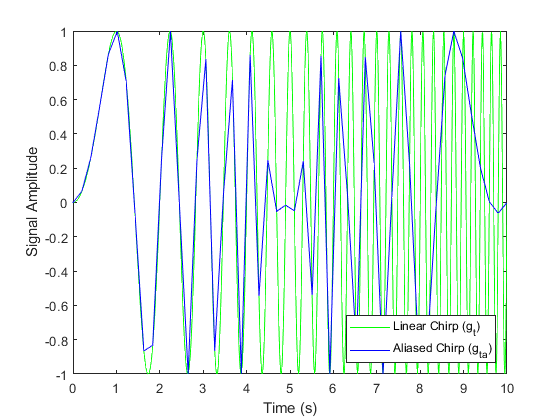

plot(t,g_t,'g',t_a,g_ta,'b');
xlabel('Time (s)')
ylabel('Signal Amplitude')
legend('Linear Chirp (g_t)','Aliased Chirp (g_t_a)','Location','southeast')

## Discussion

The functions `g_t` and `g_ta` were successfully plotted on the same graph for comparison. `g_t`, the 'Linear Chirp', does appear to increase linearly in frequency from 0Hz to 5Hz over 10 seconds. While g_t appears as expected, `g_ta`, the 'Aliased Chirp' does not. From t=0s to t=5s, `g_ta` tracks well with `g_t` and, though it is visibly distorted, retains the same frequency as` g_t`. At t=5s, the `g_ta` signal appears to reach a null point in its amplitude and from t=5 to t=10 appears as a "folded over" or mirrored copy of itself against t=5.

This behavior can be largely explained by the Nyquist sampling theorem. The theorem states that a waveform must be sampled at a rate equal to or greater than twice the highest frequency of which it is comprised to retain its frequency content when sampled. For a chirp signal increasing in frequency from 0Hz to 5Hz, the sampling rate must be at least 10Hz or higher for its frequency information to be preserved post-sampling. If the signal is undersampled, a phenomenon known as aliasing occurs, where the undersampled spectral contents of a signal manifest as information at other frequencies in the resultant sampled signal. 

For example, the highest measurable frequency, or Nyquist frequency, is 2.5Hz if a sampling rate of 5Hz is assumed. When the rate of `g`_ta is (for example) 3Hz, the signal is "folded back" below the Nyquist frequency of 2.5Hz by the difference between the signal frequency (3Hz) and the Nyquist frequency (2.5Hz) or 0.5Hz. Thus, the "alias" of g_ta at 3Hz appears as a 2Hz waveform. This "folding" behvior explains the mirroring of the observed resultant signal against the "axis" t=5 when the signal is undersampled.

Other, more minor differences between` g_t` and `g_ta` can be explained as low-resolution errors in `g_ta` due to the relatively low sampling rate. Even with `g_ta` being sufficiently sampled from t=0 to t=5, there are fewer sample points in `g_ta` to resolve `g_ta` as finely as `g_t.` This is especially apparent at the peaks of `g_ta`.

## References

- [https://www.mathworks.com/help/signal/ref/chirp.html](https://www.mathworks.com/help/signal/ref/chirp.html)

- DOWNEY, A. B. (2016). 2.3 Aliasing. In *THINK DSP: Digital signal processing in python* (pp. 17-19). Needham, MA: SHROFF  & DISTR.